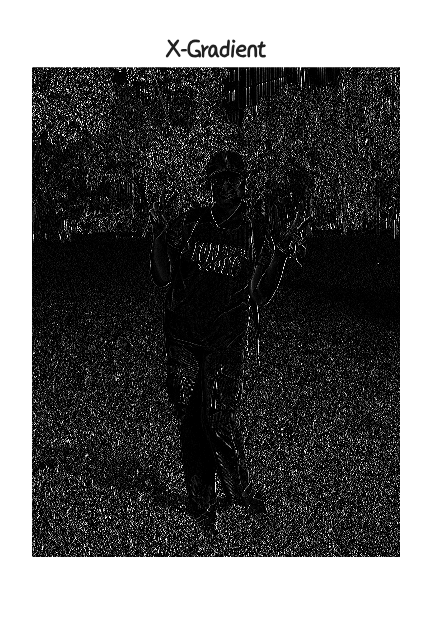

%% Sobel operator %%

aa=rgb2gray(imread('DK.jpg')); 
a=double(aa);
[row col]=size(a);

% Sobel Masks
w1=[-1 -2 -1; 0 0 0; 1 2 1];    % Horizontal edges
w2=[-1 0 1; -2 0 2; -1 0 1];    % Vertical edges

for x=2:row-1
    for y=2:col-1
        % Calculate Horizontal Gradient (a1)
        a1(x,y)=w1(1)*a(x-1,y-1)+w1(2)*a(x-1,y)+w1(3)*a(x-1,y+1)+w1(4)*...
                a(x,y-1)+w1(5)*a(x,y)+w1(6)*a(x,y+1)+w1(7)*...
                a(x+1,y-1)+w1(8)*a(x+1,y)+w1(9)*a(x+1,y+1);
            
        % Calculate Vertical Gradient (a2)
        a2(x,y)=w2(1)*a(x-1,y-1)+w2(2)*a(x-1,y)+w2(3)*a(x-1,y+1)+w2(4)*...
                a(x,y-1)+w2(5)*a(x,y)+w2(6)*a(x,y+1)+w2(7)*...
                a(x+1,y-1)+w2(8)*a(x+1,y)+w2(9)*a(x+1,y+1);
    end
end

a3=a1+a2; %% Final gradient values %%

figure(1)
imshow(uint8(a1)) % X-gradient
title('X-Gradient')
exportgraphics(gcf, 'S1.png', 'Resolution', 300)

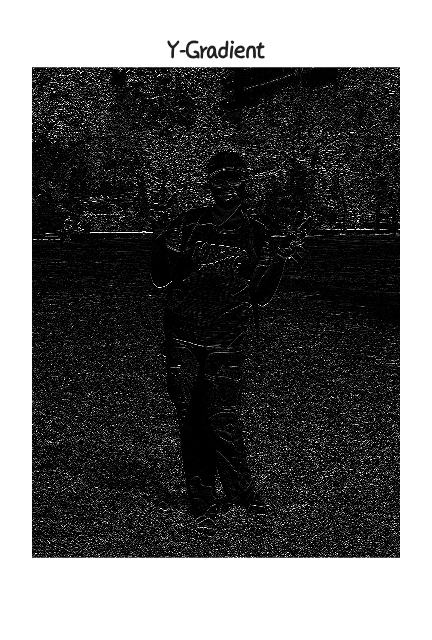


figure(2)
imshow(uint8(a2)) % Y-gradient
title('Y-Gradient')
exportgraphics(gcf, 'S2.png', 'Resolution', 300)

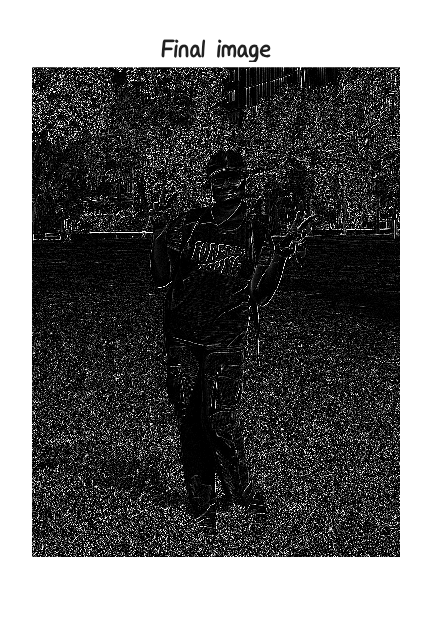


figure(3)
imshow(uint8(a3)) % Final gradient
title('Final image')
exportgraphics(gcf, 'S3.png', 'Resolution', 300)